# Transfer Learning: VGG-16

Author: Christopher Couture Del Valle

Date: 11/22/2021

## Load the Dataset

In this sections we load the images required for training and testing

% Clear workspace
clear; close all; clc;

% Image datastore
imds = imageDatastore("/Users/chris/Documents/Matlab/cell_images/cell_images/",'IncludeSubfolders',true, "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\cell_images\Parasitized\C100P61ThinF_IMG_20150918_144104_cell_162.png';
                              ' ...\cell_images\Parasitized\C100P61ThinF_IMG_20150918_144104_cell_163.png';
                              ' ...\cell_images\Parasitized\C100P61ThinF_IMG_20150918_144104_cell_164.png'
                               ... and 27555 more
                              }
                     Folders: {
                              'C:\Users\chris\Documents\Matlab\cell_images\cell_images'
                              }
                      Labels: [Parasitized; Parasitized; Parasitized ... and 27555 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"



%Total count of each class
total_count = countEachLabel(imds)

total_count = 2×2 table
       Label       Count
    ___________    _____

    Parasitized    13779
    Uninfected     13779


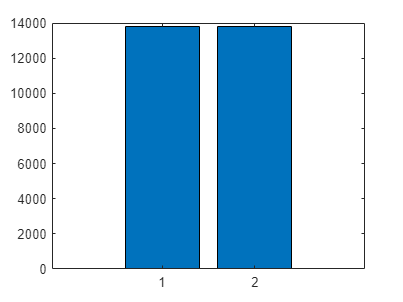


%Visualize both classes in bar chart
bar(total_count.Count)

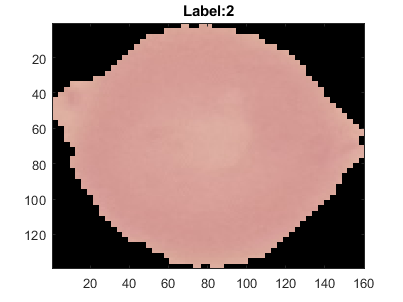


%Visualize image from each label
%Better suited for instances with more labels, included for 
%proof of concept

double_labels = double(imds.Labels);
for idx=1:length(unique(imds.Labels))
    
    %Find one index of each image
    current_label_idx = find(double_labels==idx,1,"first");
    
    %Read the file
    I = readimage(imds,current_label_idx);
    
    figure(1);
    imagesc(I);
    title(sprintf('Label:%d',double_labels(current_label_idx)));
    %Long pause since there are only two images
    pause(2.5);
end

## Visualize the Images

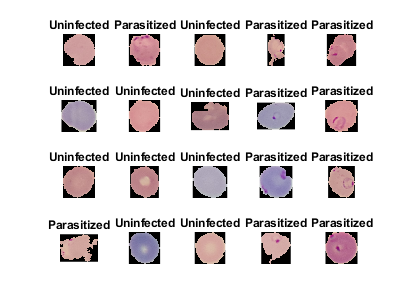

% Number of Images
num_images=length(imds.Labels);

% Visualize random 20 images
perm=randperm(num_images,20);
figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(imds.Files{perm(idx)}));
 title(sprintf('%s',imds.Labels(perm(idx))))

end

## Visualize Preprocessed Images

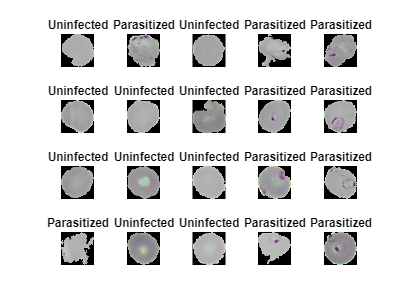

figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(preprocess_malaria_images(imds.Files{perm(idx)},[250 250]))
 title(sprintf('%s',imds.Labels(perm(idx))))
end

## Training and Validation Dataset

% Split the Training and Testing Dataset
train_percent=0.90;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');
% Split the Training and Validation
valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);
valid_count=countEachLabel(imdsValid);
test_split=countEachLabel(imdsTest);

## Transfer Learning: VGG16

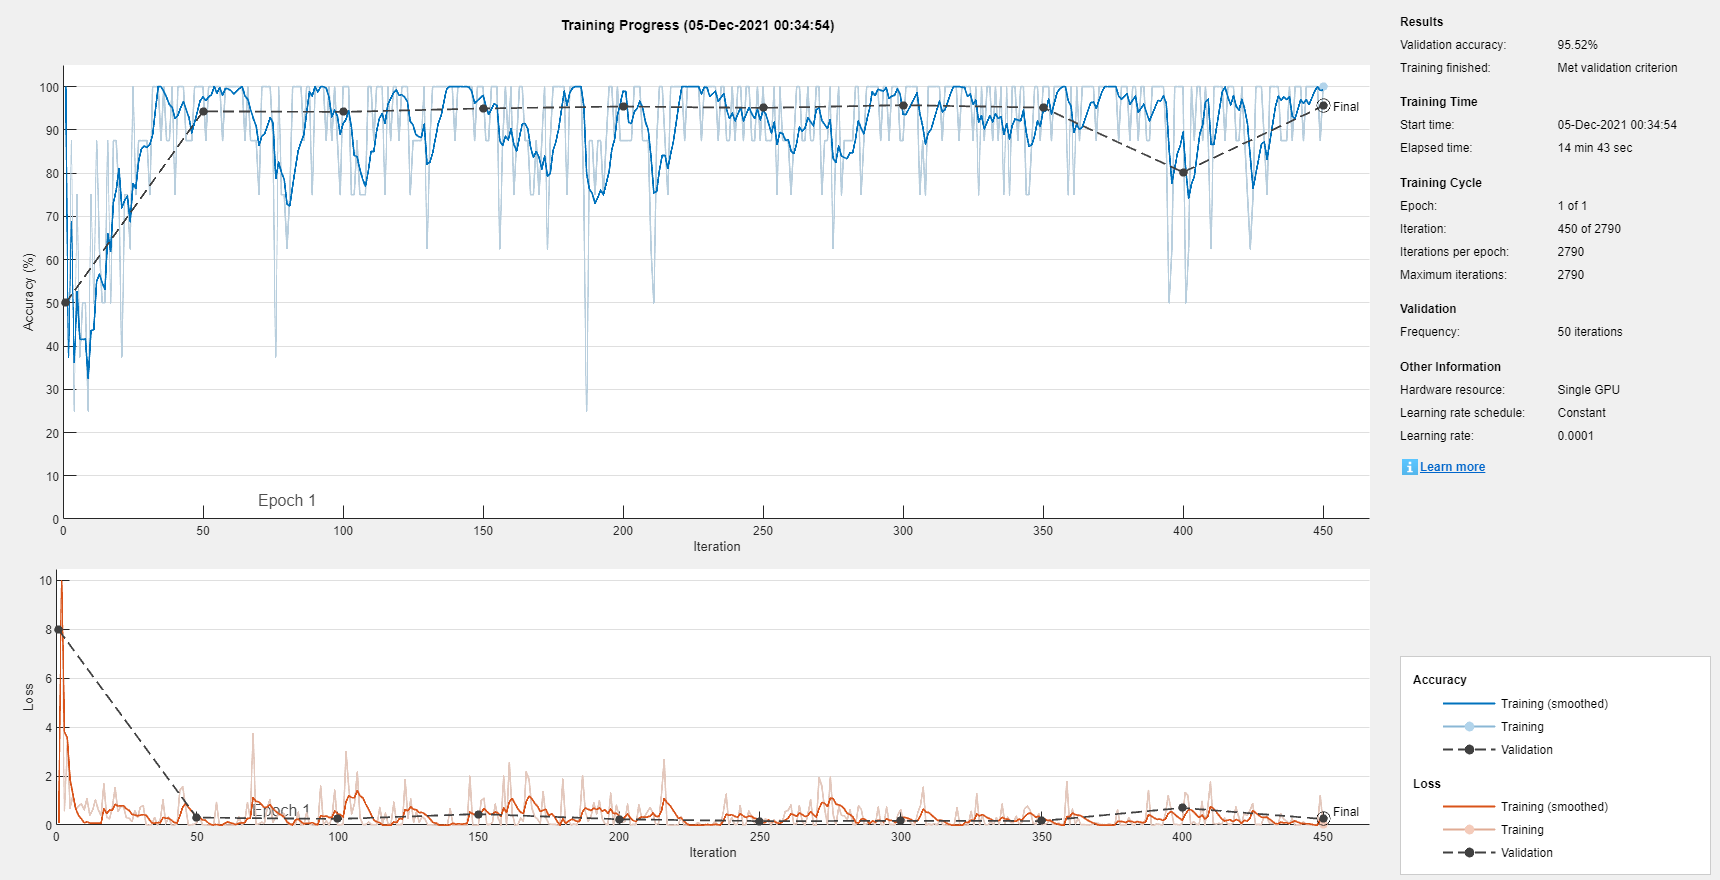

img_size=[224 224];

% Load VGG16
net=vgg16;
 
% Transfer the layers except the last 3 layers
layersTransfer=net.Layers(1:end-3);
 
% Clear the existing VGG16 architecture
clear net;
 
% Define the new layers 
numClasses=numel(categories(imdsTrain.Labels));
 
% New layers 
layers=[
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];


% Preprocessing Technique
%imdsTrain.ReadFcn=@(filename)reshape_image(filename,img_size);
%imdsValid.ReadFcn=@(filename)reshape_image(filename,img_size);

imdsTrain.ReadFcn=@(filename)preprocess_malaria_images(filename,img_size);
imdsValid.ReadFcn=@(filename)preprocess_malaria_images(filename,img_size);

options=trainingOptions('adam', ...
    'MiniBatchSize',8, ...
    'MaxEpochs',1, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',imdsValid, ...
    'ValidationFrequency',50,'ValidationPatience',4, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    "ExecutionEnvironment","gpu");

% Data Augumentation
augmenter = imageDataAugmenter( ...
     'RandRotation',[-5 5],'RandXReflection',1,...
     'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);

% Resizing all training images to [224 224] for VGG16 architecture

auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
%auimds = augmentedImageDatastore([224 224],imdsTrain);

% Training
netTransfer = trainNetwork(auimds,layers,options);

%save vgg_model netTransfer imdsTrain imdsTest imdsValid


## Testing Dataset

%Image Datastore
g = gpuDevice(1);

reset(g)

%load vgg_model netTransfer imdsTrain imdsTest imdsValid


%imdsTest.ReadFcn=@(filename)reshape_image(filename,img_size);
%imdsTest.ReadFcn=@(filename)reshape_grayscale_histeq(filename,img_size);
imdsTest.ReadFcn=@(filename)preprocess_malaria_images(filename,img_size);
% Resizing all testing images to [224 224] for ResNet architecture   
augtestimds = augmentedImageDatastore([224 224],imdsTest);
   
% Testing and their corresponding Labels and Posterior for each Case
[predicted_labels,posterior] = classify(netTransfer,augtestimds, "ExecutionEnvironment","cpu");


% for idx=1:length(imdsTest.Files)
%     
%     I = reshape_image(imdsTest.Files{idx},img_size);
%     figure;
%     imagesc(I);
%     colormap("gray");
%     title(sprintf('Predicted Label:%s', predicted_labels(idx)));
%     pause(0.3)
% end

## Performance Study

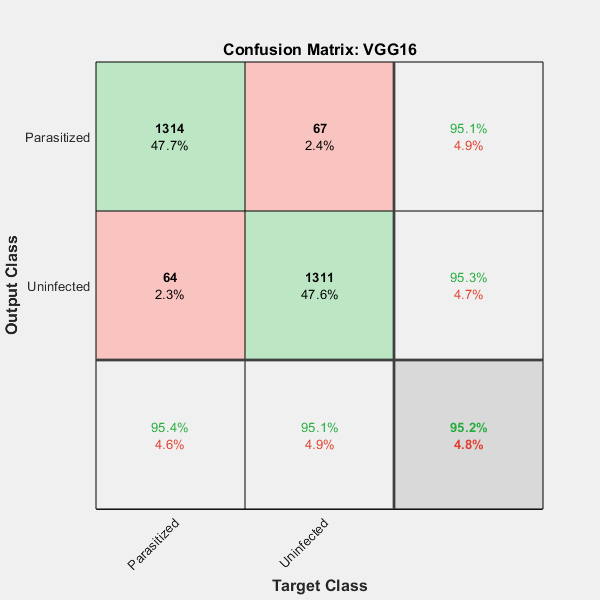

% Actual Labels
actual_labels=imdsTest.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels)
title('Confusion Matrix: VGG16');

## ROC Curve

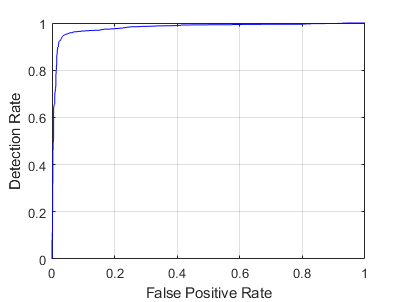

test_labels=double(nominal(imdsTest.Labels));

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


AUC

AUC = 0.9804

Function: Preprocessing Function, Color Constancy

function Iout=preprocess_malaria_images(filename,desired_size)

% Read the Image
I=imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I=cat(3,I,I,I);
end

% Conversion to Double for calculation purposes
I=double(I);

% Mean Calculation
Ir=I(:,:,1);mu_red=mean(Ir(:));
Ig=I(:,:,2);mu_green=mean(Ig(:));
Ib=I(:,:,3);mu_blue=mean(Ib(:));
mean_value=(mu_red+mu_green+mu_blue)/3;

% Scaling the Image for Color constancy
Iout(:,:,1)=I(:,:,1)*mean_value/mu_red;
Iout(:,:,2)=I(:,:,2)*mean_value/mu_green;
Iout(:,:,3)=I(:,:,3)*mean_value/mu_blue;

% Converting it back to uint8
Iout=uint8(Iout);

% Resize the image
Iout=imresize(Iout,[desired_size(1) desired_size(2)]);
end

Function: Reshape Image

function Iout = reshape_image(filename,img_size)

I = imread(filename);
Iout=imresize(I,[224 224]);

end

Function: Grayscale and Histogram Equaliztion

function Iout = reshape_grayscale_histeq(filename,img_size)

I=imread(filename);
I=rgb2gray(I);
I=histeq(I);

Iout=imresize(I,img_size);
end